
$$\phi = \frac{N \cdot I}{R_{total}}$$



$$R_{total} = R_{vertical\_in} + R_{vertical\_out} + R_{horizontal\_top} +  R_{horizontal\_bottom}$$



$$R_{vertial\_in} = \frac{l_a-l_c}{\mu  \cdot S_2} + \frac{l_c}{\mu_0  \cdot S_2}$$



$$R_{vertial\_out} = \frac{l_a}{\mu  \cdot S_1}$$



$$R_{horizontal\_top} = R_{horizontal\_bottom} = \frac{l_b}{\mu  \cdot S_3}$$



$$S_2 = \frac{ \pi}{4} \cdot d_4^2$$



$$S_1 = \frac{ \pi}{4} \cdot (d_1^2 - d_2^2)$$



$$S_3 = \frac{ \pi \cdot l_1}{4} \cdot (d_1 + d_2)$$


for grid arrangement it should be 0.785, for lattice theoretical max is 0.907


$$\lambda \approx 0.85$$



$$N \cdot I = \frac{l_4 \cdot (d_2 - d_3) \cdot \lambda}{A_{wire}$$



$$I = \frac{V}{R}$$



$$R \sim \frac{1}{A_{wire}$$



$$I \sim V \cdot A_{write}$$



$$N \cdot I \sim  \frac{l_4 \cdot (d_2 - d_3) \cdot \lambda}{A_{wire}} \cdot V \cdot A_{wire}$$


Thus:  


$$\frac{\delta (N \cdot I)}{\delta A_{wire}} = 0$$


## Derivatives


$$F_{mag} = \frac{1 \cdot \phi^2}{2 \cdot \mu_0 \cdot S_2}$$


Force = 0.5 * 2.7E-4^2 / (1.25663706212E-6 * pi * 0.0049^2)

Force = 384.5436

Max_number_of_turns = 10E-3 * 50E-3 / (0.25E-3^2)

Max_number_of_turns = 8.0000e+03


$$\frac{\delta F_{mag}}{\delta \phi} = \frac{\phi}{\mu_0 \cdot S_2}$$



$$\frac{\delta \phi}{\delta R_{total}} = -\frac{N \cdot I}{R_{total}^2}$$


### Lc


$$\frac{\delta \phi}{\delta l_c} = \frac{\delta \phi}{\delta R_{total}} \cdot \frac{\delta R_{total}}{\delta l_c}$$



$$\frac{\delta R_{total}}{\delta l_c} = \frac{\mu - \mu_0}{\mu \cdot \mu_0 \cdot S_2}$$



$$\frac{\delta \phi}{\delta l_c} = -\frac{N \cdot I}{R_{total}^2} \cdot \frac{\mu - \mu_0}{\mu \cdot \mu_0 \cdot S_2}$$



$$\frac{\delta F_{mag}}{\delta l_c} = -\frac{\phi}{\mu_0 \cdot S_2} \cdot \frac{N \cdot I}{R_{total}^2} \cdot \frac{\mu - \mu_0}{\mu \cdot \mu_0 \cdot S_2}$$



$$\frac{\delta F_{mag}}{\delta l_c} = -\frac{\phi^2\cdot (\mu - \mu_0)}{\mu \cdot \mu_0^2 \cdot S_2^2 \cdot R_{total}} $$


lcs = 0:1E-4:0.5E-3;
tempR = theoricTotalReluctance(3E-3,25E-3,3E-3,lcs,18E-3,16E-3,8E-3);
tempPhi = 400 ./ tempR;
mu0 = 1.25663706212E-6;
mu = 850 * mu0;
S2 = 0.25*pi*8E-3^2;
tempF = 0.5 .* tempPhi.^2 ./ (mu0 * S2)

tempF =   637.3431  141.5764   60.5833   33.4475   21.1696   14.5930


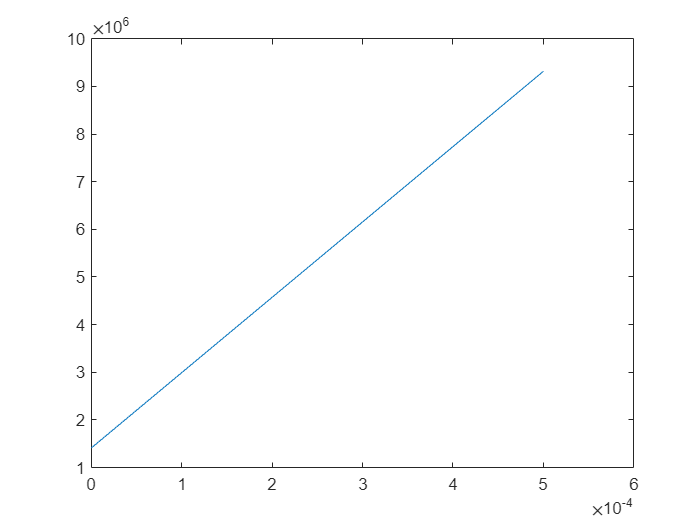

tempdFmag_dlc = -tempPhi.^2 .* (mu - mu0) ./ (mu * mu0^2 * S2^2 .* tempR);
figure
plot(lcs,tempR)

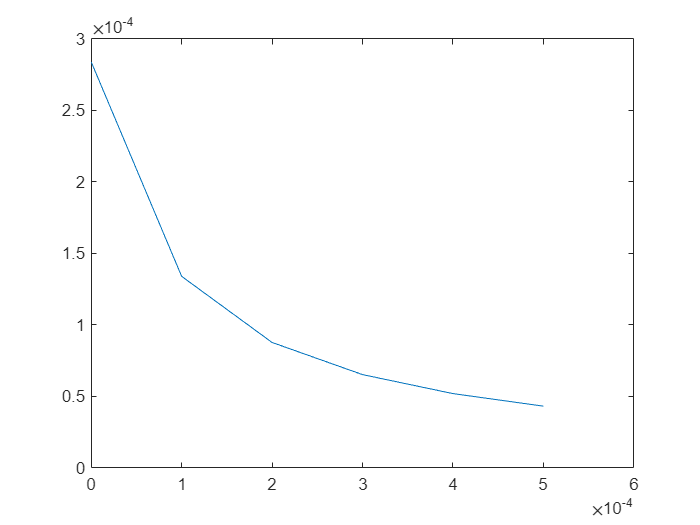

figure
plot(lcs,tempPhi)

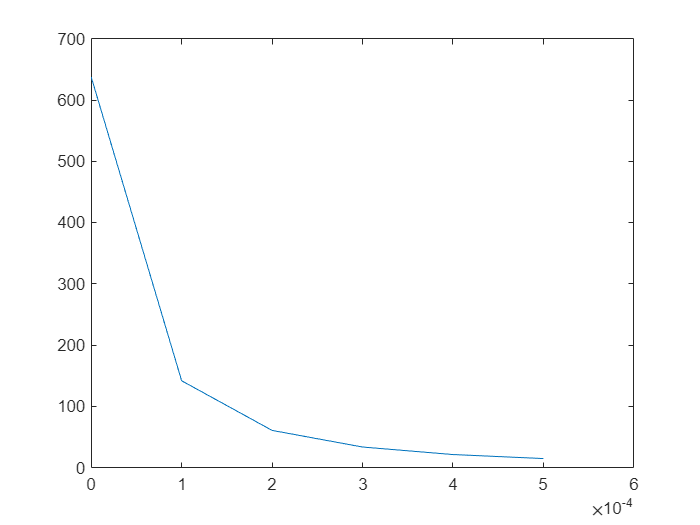

figure
plot(lcs,tempF)

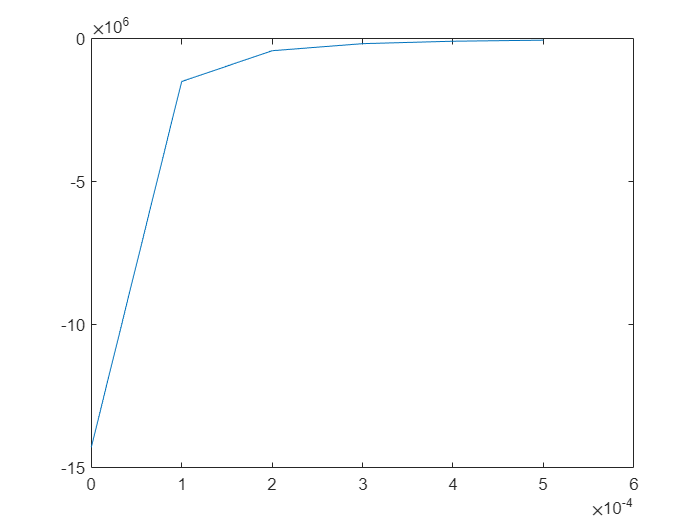

figure
plot(lcs,tempdFmag_dlc)

(tempF(6) - tempF(5))/lcs(2)

ans = -6.5766e+04

tempdFmag_dlc(5)

ans = -8.6557e+04

tempdFmag_dlc(6)

ans = -4.9539e+04

(0.5*(tempdFmag_dlc(6)+tempdFmag_dlc(5))-(tempF(6) - tempF(5))/lcs(2))/tempdFmag_dlc(5)

ans = 0.0264

### S2


$$F_{mag} = \frac{1 \cdot \phi^2}{2 \cdot \mu_0 \cdot S_2}$$



$$F_{mag} = \frac{1}{2 \cdot \mu_0} \cdot \phi^2 \cdot  \frac{1}{ S_2}$$



$$\frac{\delta F_{mag}}{\delta d_4} = \frac{1}{2 \cdot \mu_0} \cdot \left(2 \cdot \frac{\delta \phi}{\delta d_4} \cdot \phi  \cdot  \frac{1}{ S_2} - \phi^2 \cdot \frac{\delta S_2}{\delta d_4} \cdot \frac{1}{S_2^2}\right)$$



$$\phi = \frac{N \cdot I}{R_{total}}$$



$$ \frac{\delta \phi}{\delta d_4} = \frac{\frac{\delta N \cdot I}{\delta d_4} \cdot R_{total} - N \cdot I \cdot \frac{\delta R_{total}}{\delta d_4}} {R_{total}^2}$$



$$N \cdot I = \frac{l_4 \cdot (d_2 - d_3) \cdot \lambda}{A_{wire}} = \frac{l_4 \cdot (d_2 - (d_4 + C)) \cdot \lambda}{A_{wire}}$$



$$\frac{\delta N \cdot I}{\delta d_4} = - \frac{l_4 \cdot \lambda}{A_{wire}}$$



$$R_{vertial\_in} = \frac{l_a-l_c}{\mu  \cdot S_2} + \frac{l_c}{\mu_0  \cdot S_2}$$



$$\frac{\delta R_{total}}{\delta S_2} = -2 \cdot \frac{l_c \cdot (\mu - \mu_0) + \mu_0 \cdot la}{\mu \cdot \mu_0 \cdot S_2^3}$$



$$\frac{\delta S_2}{\delta d_4} = \frac{\pi}{2} \cdot d_4$$



$$\frac{\delta R_{total}}{\delta d_4} = \frac{\delta R_{total}}{\delta S_2} \cdot \frac{\delta S_2}{\delta d_4} = -2 \cdot \frac{l_c \cdot (\mu - \mu_0) + \mu_0 \cdot la}{\mu \cdot \mu_0 \cdot S_2^3} \cdot \frac{\pi}{2} \cdot d_4$$



$$R_{vertial\_in} = \frac{l_a-l_c}{\mu  \cdot S_2} + \frac{l_c}{\mu_0  \cdot S_2}$$



$$R_{vertial\_in} = \frac{\mu_0 \cdot \left(l_a-l_c\right) + \mu \cdot l_c}{\mu  \cdot \mu_0  \cdot \frac{\pi}{4}\cdot d_4^2}$$



$$\frac{\delta R_{vertial\_in}}{\delta d_4} = \frac{\delta R_{total}}{\delta d_4} = -2 \frac{\mu_0 \cdot \left(l_a-l_c\right) + \mu \cdot l_c}{\mu  \cdot \mu_0  \cdot \frac{\pi}{4}\cdot d_4^3}$$



$$ \frac{\delta \phi}{\delta d_4} = \frac{ \left(- \frac{l_4 \cdot \lambda}{A_{wire}}\right)\cdot R_{total} - N \cdot I \cdot \left( -2 \frac{\mu_0 \cdot \left(l_a-l_c\right) + \mu \cdot l_c}{\mu  \cdot \mu_0  \cdot \frac{\pi}{4}\cdot d_4^3} \right) } {R_{total}^2}$$



$$\frac{\delta F_{mag}}{\delta d_4} = \frac{1}{2 \cdot \mu_0} \cdot \left[2 \cdot \left( \frac{ \left(- \frac{l_4 \cdot \lambda}{A_{wire}}\right)\cdot R_{total} - N \cdot I \cdot \left( -8 \frac{\mu_0 \cdot \left(l_a-l_c\right) + \mu \cdot l_c}{\mu  \cdot \mu_0  \cdot \pi \cdot d_4^3} \right) } {R_{total}^2} \right) \cdot \phi  \cdot  \frac{1}{ S_2} - \phi^2 \cdot \frac{\pi}{2} \cdot d_4 \cdot \frac{1}{S_2^2}\right]$$


d4s = 8E-3:1E-3:25E-3;
[tempFdd4, Fs] = dFmag_dd4(3E-3,25E-3,3E-3,25E-3,0.5E-3,33E-3,30E-3,d4s+3E-3,d4s)

rTot = 	1.0e+06 *

    9.0018    7.2330    5.9678    5.0317    4.3197    3.7656    3.3259    2.9712    2.6809    2.4403    2.2387    2.0681    1.9224    1.7970    1.6884    1.5936    1.5104    1.4370


N =         1835        1738        1642        1545        1448        1352        1255        1159        1062         965         869         772         676         579         482         386         289         193


l_wire =   236.3577  229.3237  221.8153  213.5655  204.7062  195.3819  185.3068  174.7731  163.4822  151.5818  139.2322  126.1161  112.5570   98.2250   83.2836   67.9087   51.7515   35.1670


R_wire =     9.2180    8.9436    8.6508    8.3291    7.9835    7.6199    7.2270    6.8162    6.3758    5.9117    5.4301    4.9185    4.3897    3.8308    3.2481    2.6484    2.0183    1.3715


tempFdd4 = 	1.0e+03 *

    5.7318    5.0933    4.5824    4.1645    3.8162    3.5215    3.2689    3.0499    2.8584    2.6894    2.5391    2.4047    2.2837    2.1742    2.0747    1.9839    1.9006    1.8240


Fs =    19.2411   17.1032   15.3929   13.9935   12.8274   11.8407   10.9949   10.2619    9.6205    9.0546    8.5516    8.1015    7.6964    7.3299    6.9968    6.6925    6.4137    6.1571


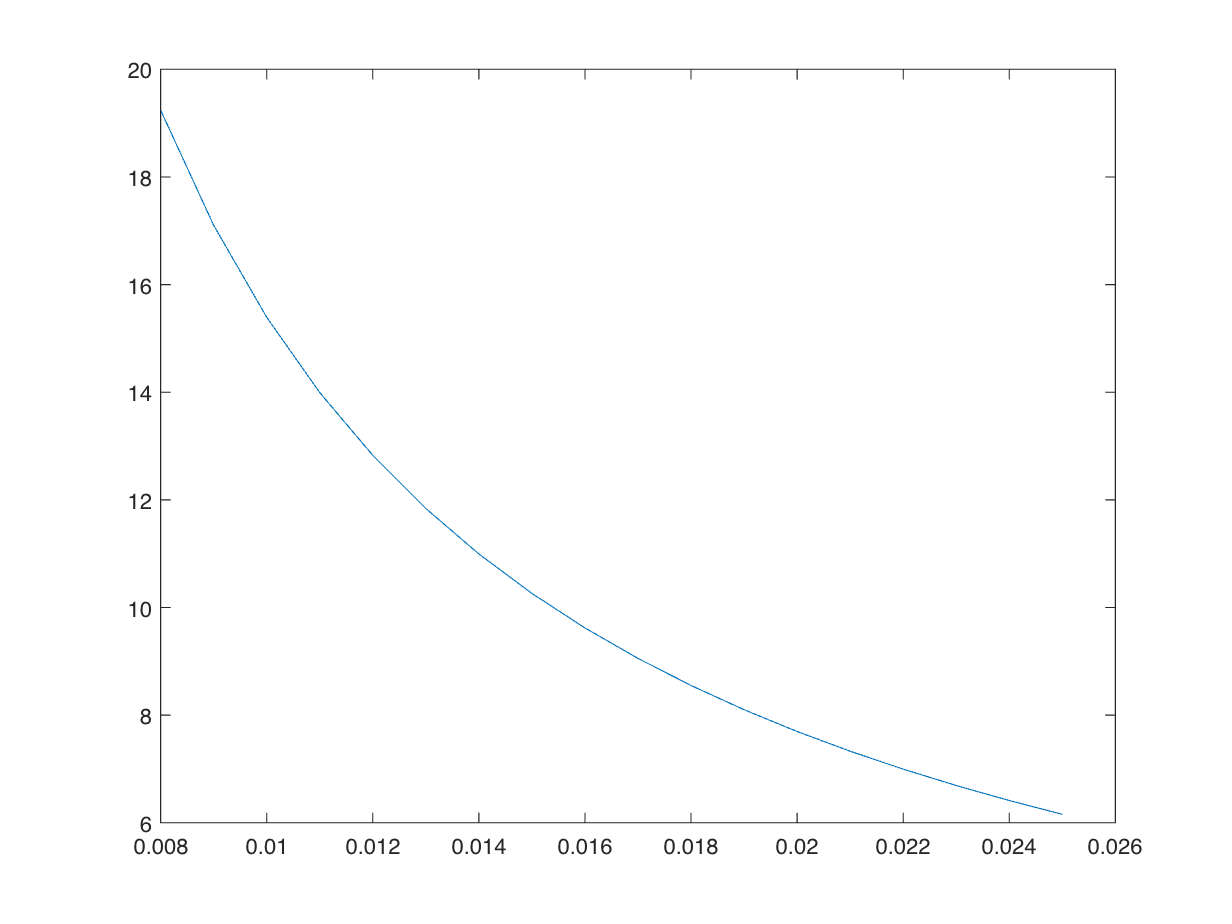

figure
plot(d4s,Fs)

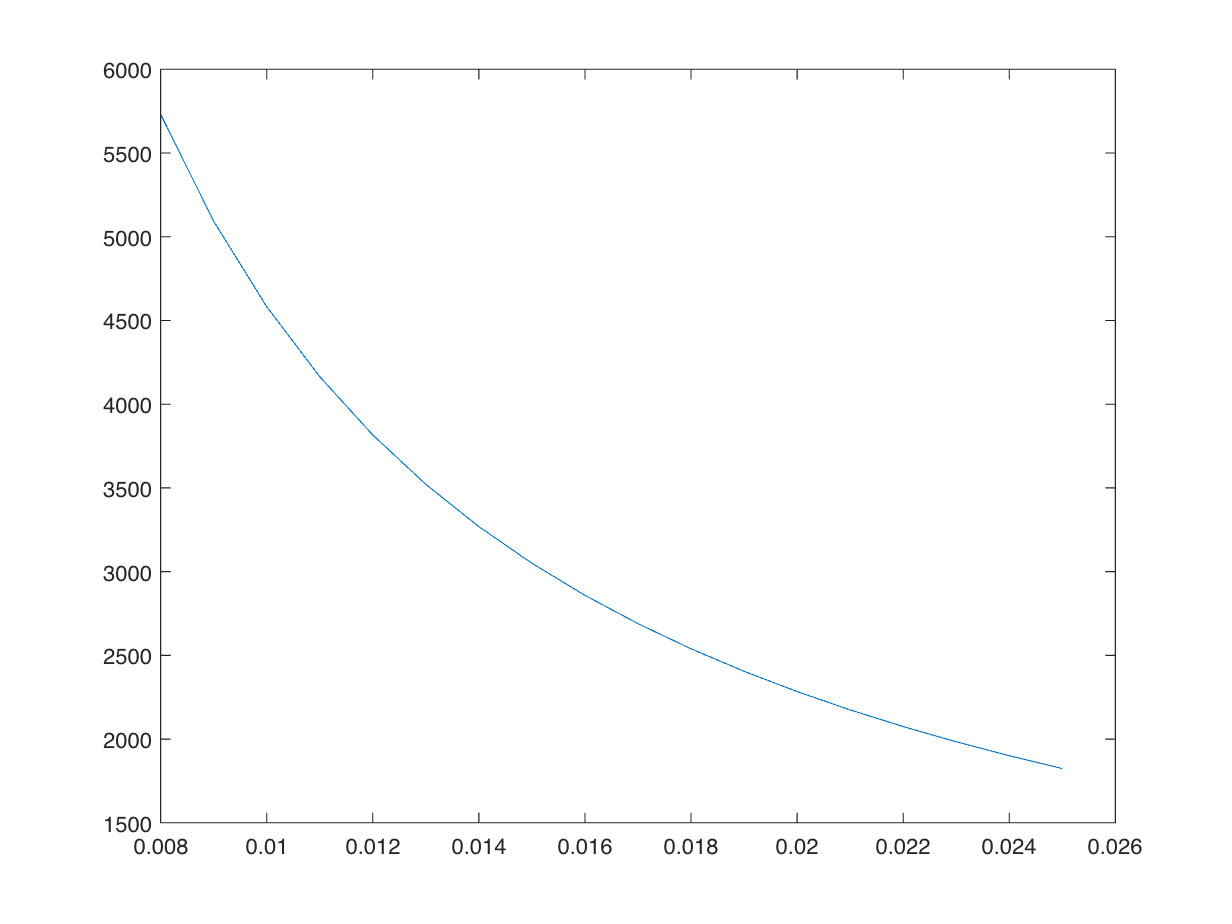

figure
plot(d4s,tempFdd4)

(Fs(6) - Fs(5))/(d4s(6)-d4s(5))

ans = -986.7217

tempFdd4(5)

ans = 3.8162e+03

tempFdd4(6)

ans = 3.5215e+03

(0.5*(tempFdd4(6)+tempFdd4(5))-(Fs(6) - Fs(5))/(d4s(2)-d4s(1)))/tempFdd4(5)

ans = 1.2199


syms theta y(theta) x(y) mu mu0
x = x(y)

$$x = x\left(y\left(\theta \right)\right)$$

Dyt = diff(y,theta)

$$Dyt(theta) = \frac{\partial }{\partial \theta }y\left(\theta \right)$$

Dxt = diff(x,theta)

$$Dxt = x^{\prime }\left(y\left(\theta \right)\right)\,\frac{\partial }{\partial \theta }y\left(\theta \right)$$

syms d4 phi(d4) S2(d4)
Fmag = 0.5 / mu0 * phi^2 / S2

$$Fmag(d4) = \frac{{\varphi \left(d_{4}\right)}^{2}}{2\,\mu_{0}\,S_{2}\left(d_{4}\right)}$$


$$\phi = \frac{N \cdot I}{R_{total}}$$


syms N I Rtotal
phi = N * I / Rtotal

$$phi = \frac{\text{I}\,N}{\mathrm{Rtotal}}$$


$$R_{total} = R_{vertical\_in} + R_{vertical\_out} + R_{horizontal\_top} +  R_{horizontal\_bottom}$$


syms Rvert_in Rvert_out Rhor


$$R_{vertial\_in} = \frac{l_a-l_c}{\mu  \cdot S_2} + \frac{l_c}{\mu_0  \cdot S_2}$$


syms la lc
Rvert_in = (la - lc) / (mu*S2) + lc/(mu0*S2)

$$Rvert\_in(d4) = \frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(d_{4}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(d_{4}\right)}$$


$$R_{vertial\_out} = \frac{l_a}{\mu  \cdot S_1}$$


syms S1
Rvert_out = la / (mu*S1)

$$Rvert\_out = \frac{\mathrm{la}}{S_{1}\,\mu }$$


$$R_{horizontal\_top} = R_{horizontal\_bottom} = \frac{l_b}{\mu  \cdot S_3}$$


syms S3 lb
Rhor = lb / (mu*S3)

$$Rhor = \frac{\mathrm{lb}}{S_{3}\,\mu }$$

Rtotal = Rvert_in + Rvert_out + Rhor

$$Rtotal(d4) = \frac{\mathrm{la}}{S_{1}\,\mu }+\frac{\mathrm{lb}}{S_{3}\,\mu }+\frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(d_{4}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(d_{4}\right)}$$

diff(Rtotal,d4)

$$ans(d4) = -\frac{\mathrm{lc}\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{\mu_{0}\,{S_{2}\left(d_{4}\right)}^{2}}-\frac{\left(\mathrm{la}-\mathrm{lc}\right)\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{\mu \,{S_{2}\left(d_{4}\right)}^{2}}$$


phi = N * I / Rtotal

$$phi(d4) = \frac{\text{I}\,N}{\frac{\mathrm{la}}{S_{1}\,\mu }+\frac{\mathrm{lb}}{S_{3}\,\mu }+\frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(d_{4}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(d_{4}\right)}}$$

diff(phi,d4)

$$ans(d4) = \frac{\text{I}\,N\,\left(\frac{\mathrm{lc}\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{\mu_{0}\,{S_{2}\left(d_{4}\right)}^{2}}+\frac{\left(\mathrm{la}-\mathrm{lc}\right)\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{\mu \,{S_{2}\left(d_{4}\right)}^{2}}\right)}{{\left(\frac{\mathrm{la}}{S_{1}\,\mu }+\frac{\mathrm{lb}}{S_{3}\,\mu }+\frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(d_{4}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(d_{4}\right)}\right)}^{2}}$$

Fmag = 0.5 / mu0 * phi^2 / S2

$$Fmag(d4) = \frac{{\text{I}}^{2}\,N^{2}}{2\,\mu_{0}\,S_{2}\left(d_{4}\right)\,{\left(\frac{\mathrm{la}}{S_{1}\,\mu }+\frac{\mathrm{lb}}{S_{3}\,\mu }+\frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(d_{4}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(d_{4}\right)}\right)}^{2}}$$

dFmag = diff(Fmag,d4)

$$dFmag(d4) = \begin{array}{l} \frac{{\text{I}}^{2}\,N^{2}\,\left(\frac{\mathrm{lc}\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{\mu_{0}\,{S_{2}\left(d_{4}\right)}^{2}}+\frac{\left(\mathrm{la}-\mathrm{lc}\right)\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{\mu \,{S_{2}\left(d_{4}\right)}^{2}}\right)}{\mu_{0}\,S_{2}\left(d_{4}\right)\,{\sigma_{1}}^{3}}-\frac{{\text{I}}^{2}\,N^{2}\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)}{2\,\mu_{0}\,{S_{2}\left(d_{4}\right)}^{2}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{la}}{S_{1}\,\mu }+\frac{\mathrm{lb}}{S_{3}\,\mu }+\frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(d_{4}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(d_{4}\right)} \end{array}$$

simplify(diff(Fmag,d4))

$$ans(d4) = \begin{array}{l} -\frac{{\text{I}}^{2}\,N^{2}\,{S_{1}}^{2}\,{S_{3}}^{2}\,\mu^{2}\,\mu_{0}\,\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)\,\left(\sigma_{2}+\sigma_{1}-S_{1}\,S_{3}\,\mathrm{la}\,\mu_{0}-S_{1}\,S_{3}\,\mathrm{lc}\,\mu +S_{1}\,S_{3}\,\mathrm{lc}\,\mu_{0}\right)}{2\,{\left(\sigma_{2}+\sigma_{1}+S_{1}\,S_{3}\,\mathrm{la}\,\mu_{0}+S_{1}\,S_{3}\,\mathrm{lc}\,\mu -S_{1}\,S_{3}\,\mathrm{lc}\,\mu_{0}\right)}^{3}}\\ \mathrm{where}\\ \sigma_{1}=S_{1}\,\mathrm{lb}\,\mu_{0}\,S_{2}\left(d_{4}\right)\\ \sigma_{2}=S_{3}\,\mathrm{la}\,\mu_{0}\,S_{2}\left(d_{4}\right) \end{array}$$

dFmag(5E-3)

$$ans = \begin{array}{l} \frac{{\text{I}}^{2}\,N^{2}\,\left(\frac{\left({\left(\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)\right)|}_{d_{4}=\frac{1}{200}}\right)\,\left(\mathrm{la}-\mathrm{lc}\right)}{\mu \,\sigma_{2}}+\frac{\mathrm{lc}\,\left({\left(\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)\right)|}_{d_{4}=\frac{1}{200}}\right)}{\mu_{0}\,\sigma_{2}}\right)}{\mu_{0}\,S_{2}\left(\frac{1}{200}\right)\,{\sigma_{1}}^{3}}-\frac{{\text{I}}^{2}\,N^{2}\,\left({\left(\frac{\partial }{\partial d_{4}}S_{2}\left(d_{4}\right)\right)|}_{d_{4}=\frac{1}{200}}\right)}{2\,\mu_{0}\,\sigma_{2}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{la}}{S_{1}\,\mu }+\frac{\mathrm{lb}}{S_{3}\,\mu }+\frac{\mathrm{lc}}{\mu_{0}\,S_{2}\left(\frac{1}{200}\right)}+\frac{\mathrm{la}-\mathrm{lc}}{\mu \,S_{2}\left(\frac{1}{200}\right)}\\ \sigma_{2}={S_{2}\left(\frac{1}{200}\right)}^{2} \end{array}$$

syms d1 d2 d4 d5 l1 l3 l4 mu mu0 CC PR
%syms NI(d2,l4,CC,PC)
Acoil = 0.5 * l4 * (d2 - (d4 + 3E-3))

$$Acoil = -\frac{l_{4}\,\left(d_{4}-d_{2}+\frac{3}{1000}\right)}{2}$$

var3 = double(subs(Acoil,[d2,d4,l4],[26E-3,8E-3,25E-3]))

var3 = 1.8750e-04

NI = Acoil * CC * PR

$$NI = -\frac{\mathrm{CC}\,\mathrm{PR}\,l_{4}\,\left(d_{4}-d_{2}+\frac{3}{1000}\right)}{2}$$

var2 = double(subs(NI,[CC,PR,d2,d4,l4],[10E6,0.7,26E-3,8E-3,25E-3]))

var2 = 1.3125e+03


$$R_{vertial\_in} = \frac{l_a-l_c}{\mu  \cdot S_2} + \frac{l_c}{\mu_0  \cdot S_2}$$


la = 0.5 * (l1 + l3) + l4 + 6E-3

$$la = \frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{3}{500}$$

lb = 0.25 * (d1 + d2)

$$lb = \frac{d_{1}}{4}+\frac{d_{2}}{4}$$

lc = 0.5E-3

lc = 5.0000e-04


S1 = 0.25 * (d1^2 - d2^2)

$$S1 = \frac{{d_{1}}^{2}}{4}-\frac{{d_{2}}^{2}}{4}$$

S2 = 0.25 * pi * d4^2

$$S2 = \frac{\pi \,{d_{4}}^{2}}{4}$$

S3 = 0.5 * pi * l1 * lb

$$S3 = \frac{\pi \,l_{1}\,\left(\frac{d_{1}}{4}+\frac{d_{2}}{4}\right)}{2}$$

S4 = 0.5 * pi * l3 * lb

$$S4 = \frac{\pi \,l_{3}\,\left(\frac{d_{1}}{4}+\frac{d_{2}}{4}\right)}{2}$$


Rvert_in = (la - lc) / (mu*S2) + lc/(mu0*S2)

$$Rvert\_in = \frac{1}{500\,{d_{4}}^{2}\,\mu_{0}\,\pi }+\frac{4\,\left(\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{11}{2000}\right)}{{d_{4}}^{2}\,\mu \,\pi }$$


$$R_{vertial\_out} = \frac{l_a}{\mu  \cdot S_1}$$


Rvert_out = la / (mu*S1)

$$Rvert\_out = \frac{\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{3}{500}}{\mu \,\left(\frac{{d_{1}}^{2}}{4}-\frac{{d_{2}}^{2}}{4}\right)}$$


$$R_{horizontal\_top} = R_{horizontal\_bottom} = \frac{l_b}{\mu  \cdot S_3}$$


Rhor_top = lb / (mu*S3)

$$Rhor\_top = \frac{2}{l_{1}\,\mu \,\pi }$$

Rhor_bot = lb / (mu*S4)

$$Rhor\_bot = \frac{2}{l_{3}\,\mu \,\pi }$$

Rtotal = Rvert_in + Rvert_out + Rhor_top + Rhor_bot

$$Rtotal = \frac{\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{3}{500}}{\mu \,\left(\frac{{d_{1}}^{2}}{4}-\frac{{d_{2}}^{2}}{4}\right)}+\frac{1}{500\,{d_{4}}^{2}\,\mu_{0}\,\pi }+\frac{2}{l_{1}\,\mu \,\pi }+\frac{2}{l_{3}\,\mu \,\pi }+\frac{4\,\left(\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{11}{2000}\right)}{{d_{4}}^{2}\,\mu \,\pi }$$

phi = NI / Rtotal

$$phi = -\frac{\mathrm{CC}\,\mathrm{PR}\,l_{4}\,\left(d_{4}-d_{2}+\frac{3}{1000}\right)}{2\,\left(\frac{\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{3}{500}}{\mu \,\left(\frac{{d_{1}}^{2}}{4}-\frac{{d_{2}}^{2}}{4}\right)}+\frac{1}{500\,{d_{4}}^{2}\,\mu_{0}\,\pi }+\frac{2}{l_{1}\,\mu \,\pi }+\frac{2}{l_{3}\,\mu \,\pi }+\frac{4\,\left(\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{11}{2000}\right)}{{d_{4}}^{2}\,\mu \,\pi }\right)}$$

var4 = double(subs(phi,[CC,PR,d1,d2,d4,l1,l3,l4,mu,mu0],[10E6,0.7,30E-3,26E-3,8E-3,3E-3,3E-3,25E-3,850*1.25663706212E-6,1.25663706212E-6]))

var4 = 1.3808e-04

Fmag = 0.5 * phi^2 / (mu0 * S2)

$$Fmag = \frac{{\mathrm{CC}}^{2}\,{\mathrm{PR}}^{2}\,{l_{4}}^{2}\,{\left(d_{4}-d_{2}+\frac{3}{1000}\right)}^{2}}{2\,{d_{4}}^{2}\,\mu_{0}\,\pi \,{\left(\frac{\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{3}{500}}{\mu \,\left(\frac{{d_{1}}^{2}}{4}-\frac{{d_{2}}^{2}}{4}\right)}+\frac{1}{500\,{d_{4}}^{2}\,\mu_{0}\,\pi }+\frac{2}{l_{1}\,\mu \,\pi }+\frac{2}{l_{3}\,\mu \,\pi }+\frac{4\,\left(\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{11}{2000}\right)}{{d_{4}}^{2}\,\mu \,\pi }\right)}^{2}}$$

diff(Fmag,mu)

$$ans = \begin{array}{l} \frac{{\mathrm{CC}}^{2}\,{\mathrm{PR}}^{2}\,{l_{4}}^{2}\,{\left(d_{4}-d_{2}+\frac{3}{1000}\right)}^{2}\,\left(\frac{\sigma_{3}}{\mu^{2}\,\sigma_{2}}+\frac{2}{l_{1}\,\mu^{2}\,\pi }+\frac{2}{l_{3}\,\mu^{2}\,\pi }+\frac{\sigma_{1}}{{d_{4}}^{2}\,\mu^{2}\,\pi }\right)}{{d_{4}}^{2}\,\mu_{0}\,\pi \,{\left(\frac{\sigma_{3}}{\mu \,\sigma_{2}}+\frac{1}{500\,{d_{4}}^{2}\,\mu_{0}\,\pi }+\frac{2}{l_{1}\,\mu \,\pi }+\frac{2}{l_{3}\,\mu \,\pi }+\frac{\sigma_{1}}{{d_{4}}^{2}\,\mu \,\pi }\right)}^{3}}\\ \mathrm{where}\\ \sigma_{1}=4\,\left(\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{11}{2000}\right)\\ \sigma_{2}=\frac{{d_{1}}^{2}}{4}-\frac{{d_{2}}^{2}}{4}\\ \sigma_{3}=\frac{l_{1}}{2}+\frac{l_{3}}{2}+l_{4}+\frac{3}{500} \end{array}$$

double(subs(Fmag,[CC,PR,d1,d2,d4,l1,l3,l4,mu,mu0],[10E6,0.7,30E-3,26E-3,8E-3,3E-3,3E-3,25E-3,850*1.25663706212E-6,1.25663706212E-6]))

ans = 150.9201


phi_res = double(subs(phi,[CC,PR,d1,d2,d4,l1,l3,l4,mu,mu0],[10E6,0.7,30E-3,26E-3,8E-3,3E-3,3E-3,25E-3,850*1.25663706212E-6,1.25663706212E-6]))

phi_res = 1.3808e-04

S2_res = double(subs(S2,[d4],[8E-3]))

S2_res = 5.0265e-05

0.5*phi_res^2/(S2_res * 1.25663706212E-6)

ans = 150.9201